# Spinning seed dynamics tests

addpath("physics\");
addpath("visualization\")

#### Setup seed shape

%% Geometry & material parameters
spanLength    = 0.050;   % spanwise length,  body z (m)
chordLength   = 0.015;   % chord length,     body x (m)
thickness     = 0.002;   % plate thickness           (m)
bulkDensity   = 1500;    % bulk material density     (kg/m^3)
arealDensity  = bulkDensity * thickness;   % areal density (kg/m^2)
 
%% Strip discretisation
numStrips = 10;   % number of spanwise aerodynamic strips
 
%% Time vector
% Mass is constant for this symmetric seed, but setupSeedShapeAndMass
% expects a time vector. A single-element vector is sufficient here;
% extend to a real time axis if the nut mass will vary later.
tSamples = 0;   % (s)
 
%% Seed wing polyshape  (drawing frame: x = spanwise, y = chordwise)
% Rectangle centred at the origin in both axes.
x_half = spanLength  / 2;   % half-span  in drawing x = body z (m)
y_half = chordLength / 2;   % half-chord in drawing y = body x (m)
 
wingPolyshape = polyshape( ...
    [-x_half,  x_half,  x_half, -x_half], ...   % drawing-x corners (spanwise)
    [-y_half, -y_half,  y_half,  y_half] );      % drawing-y corners (chordwise)
 
%% Nut mass & position
% Nut placed at the geometric centre -> body frame origin [0;0;0].
% For a symmetric seed with no nut mass this is trivially correct; set
% nutMass to a small representative value (or 0 if the nut is part of the
% wing density already).
nutMass = 1e-3;
nutPos  = [0; 0; 0];    % body frame [x;y;z] (m), centre of the seed
 
%% Assemble seedParamsIn
bsp.seedShape       = wingPolyshape;
bsp.seedDensity     = arealDensity;      % (kg/m^2)
bsp.seedThickness   = thickness;         % (m)
bsp.numStrips       = numStrips;
bsp.tSamples        = tSamples;          % (s)
bsp.nutMass_t       = nutMass * ones(size(tSamples));   % Nx1
bsp.nutPos_t        = repmat(nutPos, 1, numel(tSamples));   % 3xN
 
seedParamsIn.baseSeedParams = bsp;
 
%% Run setup
seedParams = setupSeedShapeAndMass(seedParamsIn);

#### Visualize seed shape

% Assumes seedParams already exists in the workspace from seedSetup_rectangular.m.
% Shows three subplots: identity pose, tilted 45 deg about body x, and
% all overlays enabled.

%% --- Test 1: flat, no rotation, all default overlays ---
figure(1)
visualizeSeedShape(seedParams, eye(3), [0;0;0], struct()); 
axis equal
grid on
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('Default (flat, no rotation)');
axis vis3d

%% --- Test 2: tilted 45 deg about body x (nose-down pitch) ---
ang   = pi/4;                          % 45 deg
rotX  = [1,      0,       0;  ...      % rotation about world x
          0, cos(ang), -sin(ang); ...
          0, sin(ang),  cos(ang)];

figure(2)
clf
visualizeSeedShape(seedParams, rotX, [0;0;0], struct());
axis equal
grid on
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('Tilted 45° about X');
axis vis3d

%% --- Test 3: all overlays on, offset position ---
opts.showPlate      = true;
opts.showPlateEdges = true;
opts.showPlateCom   = true;    % per-strip centroids
opts.showCop        = true;    % per-strip CoP markers
opts.showCom        = true;    % total CoM
opts.showNut        = true;    % nut (invisible here since nutMass = 0)

figure(3)
visualizeSeedShape(seedParams, eye(3), [0.05; 0; 0], opts);
axis equal
grid on
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('All overlays, offset position');
axis vis3d

#### Give seed some velocity and angular velocity and compute local velocity

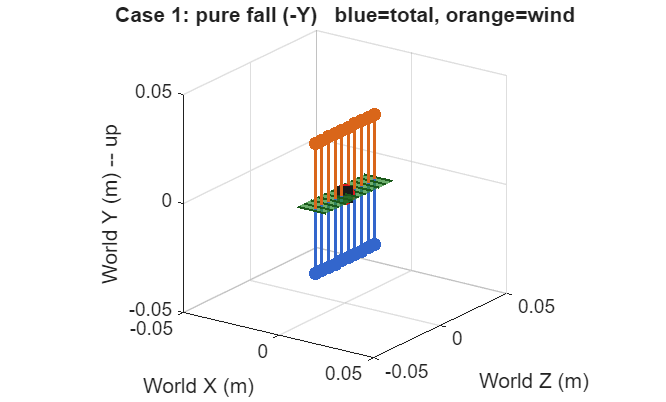

%% Test: computeSeedLocalVel + visualizeSeedLocalVels
% Assumes seedParams already exists in the workspace (run
% seedSetup_rectangular.m first). Three cases, three subplots.

% Shared pose: identity orientation, drawn at the origin.
qIdentity  = [1; 0; 0; 0];                       % body->world, no rotation
currComPos = seedParams.massParams.com_t(:, 1);  % body-frame CoM ([0;0;0] here)
rotPlot    = eye(3);
posPlot    = [0; 0; 0];

% Common visualisation options
velOpts.scale     = 0.03;   % arrow length per (m/s)
velOpts.dotSize   = 6;
velOpts.mode      = 'cop';  % draw at each centre of pressure


%% --- Case 1: pure fall (translation along -Y) ---
% Expect uniform velocity at every strip; wind points straight up (+Y).
comVel   = [0; -1; 0];   % m/s, falling
comOmega = [0;  0; 0];   % rad/s
sl1 = computeSeedLocalVel(seedParams, currComPos, qIdentity, comVel, comOmega);

figure(1)
clf
visualizeSeedShape(seedParams, rotPlot, posPlot, struct());
o = velOpts; o.showTotal = true; o.showWind = true; o.showProjected = false;
visualizeSeedLocalVels(seedParams, sl1, rotPlot, posPlot, o);
axis equal; grid on;
xlim([-0.05 0.05]);
ylim([-0.05 0.05]);
zlim([-0.05 0.05]);
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('Case 1: pure fall (-Y)   blue=total, orange=wind');
view(35, 20);

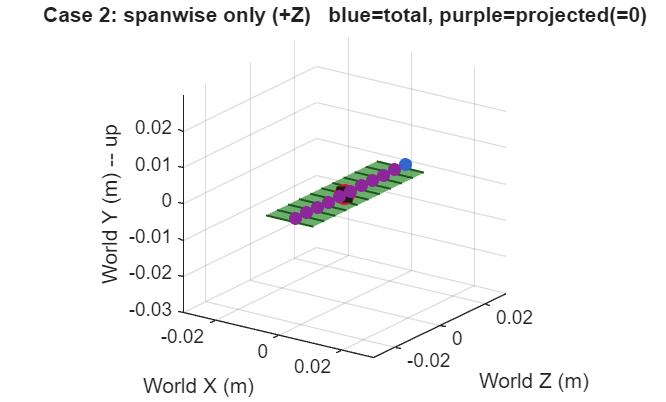


%% --- Case 2: pure spanwise motion (translation along +Z) ---
% REQUIRED CASE. Total velocity points spanwise (+Z), but the PROJECTED wind
% has its spanwise component removed -> it collapses to zero. The purple dots
% sit at the CoPs with no shaft, confirming the projection.
comVel   = [0; 0; 1];   % m/s, along span
comOmega = [0; 0; 0];
sl2 = computeSeedLocalVel(seedParams, currComPos, qIdentity, comVel, comOmega);

figure(2)
clf
visualizeSeedShape(seedParams, rotPlot, posPlot, struct());
o = velOpts; o.showTotal = true; o.showWind = false; o.showProjected = true;
visualizeSeedLocalVels(seedParams, sl2, rotPlot, posPlot, o);
axis equal; grid on;
xlim([-0.03 0.03]);
ylim([-0.03 0.03]);
zlim([-0.03 0.03]);
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('Case 2: spanwise only (+Z)   blue=total, purple=projected(=0)');
view(35, 20);

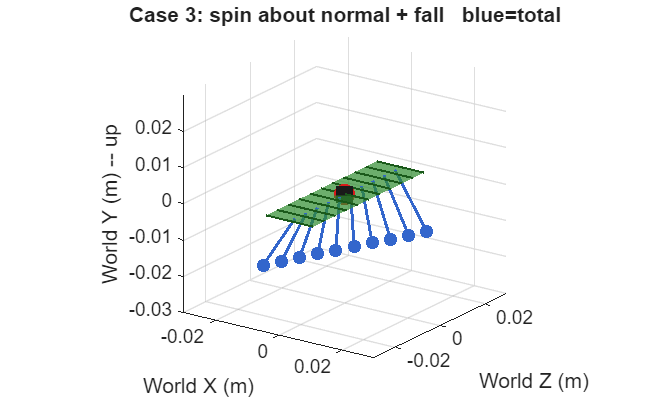


%% --- Case 3: autorotation (spin about normal +Y) while falling ---
% Rotation about the plate-normal makes the CoP velocities fan out chordwise:
% strips at +span move opposite to strips at -span. The steady fall adds a
% common downward component.
comVel   = [0; -0.5;  0];   % m/s, gentle fall
comOmega = [0;  15;   0];   % rad/s, spin about body y (normal)
sl3 = computeSeedLocalVel(seedParams, currComPos, qIdentity, comVel, comOmega);

figure(4)
clf
visualizeSeedShape(seedParams, rotPlot, posPlot, struct());
o = velOpts; o.showTotal = true; o.showWind = false; o.showProjected = false;
visualizeSeedLocalVels(seedParams, sl3, rotPlot, posPlot, o);
axis equal; grid on;
xlim([-0.03 0.03]);
ylim([-0.03 0.03]);
zlim([-0.03 0.03]);
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('Case 3: spin about normal + fall   blue=total');
view(35, 20);

#### Create seed animation

%% Test: animateSeed -- three synthetic trajectories
% Assumes seedParams exists in the workspace (run seedSetup_rectangular.m first).
% Each block builds a trajectory struct by hand, then renders it with animateSeed.
%
% Trajectory frame conventions (see computeSeedLocalVel / animateSeed):
%   quat          = [q0;q1;q2;q3] scalar-first, body->world
%   comPos_world  = CoM position, inertial frame
%   comVel_world  = CoM velocity, inertial frame
%   comOmega_body = angular velocity, body frame
% Body axes: x = chordwise, y = plate-normal, z = spanwise.
%
% Spin note: a constant body-frame spin about a single body axis keeps that
% axis fixed in inertial space (you are rotating about it), so the orientation
% is just a rotation about that axis by angle theta = omega*t. That makes the
% quaternion exact and simple to build below.

nFrames = 60;   % frames per animation


%% --- Animation 1: autorotation (spin about body y) + steady fall ---
% CoM fixed at the seed centre. Spin about the plate-normal (body y); fall
% straight down (world -Y). Shows the TOTAL local strip velocities: the fall
% gives every strip a common downward component, the spin adds a chordwise
% component that grows with spanwise distance and flips sign across the span.

T1     = 0.5;                       % duration (s)
t1     = linspace(0, T1, nFrames);  % time vector
wy     = 30;                        % spin rate about body y (rad/s)
vFall1 = 0.5;                       % fall speed (m/s)

theta1 = wy * t1;                                   % spin angle vs time
traj1.t             = t1;
traj1.quat          = [cos(theta1/2); zeros(1,nFrames); sin(theta1/2); zeros(1,nFrames)];
traj1.comPos_world  = [zeros(1,nFrames); -vFall1*t1; zeros(1,nFrames)];
traj1.comVel_world  = repmat([0; -vFall1; 0], 1, nFrames);
traj1.comOmega_body = repmat([0;  wy;     0], 1, nFrames);
% comPos_body omitted -> animateSeed falls back to massParams.com_t ([0;0;0]).

opts1 = struct();
opts1.outputFolder = 'anim1_frames';
opts1.videoFile    = 'anim1_autorotation.mp4';
opts1.fps          = 20;
opts1.axisMode     = 'follow';
opts1.zoomFactor   = 2;
opts1.showVels     = true;
opts1.velOpts.showTotal     = true;    % total strip velocities
opts1.velOpts.showProjected = false;
opts1.velOpts.scale         = 0.04;

animateSeed(seedParams, traj1, opts1);


%% --- Animation 2: spin about body z + fall forward ---
% CoM fixed at the seed centre. Spin about the spanwise axis (body z); CoM
% moves down and forward (inertial +X and -Y). Shows the PROJECTED local strip
% velocities (spanwise component removed -> the 2D in-plane flow each strip
% sees). As the seed spins about z, that in-plane wind direction rotates.

T2     = 0.5;
t2     = linspace(0, T2, nFrames);
wz     = 30;     % spin rate about body z (rad/s)
vFall2 = 0.5;    % downward speed (m/s)
vFwd2  = 0.3;    % forward speed  (m/s)

theta2 = wz * t2;
traj2.t             = t2;
traj2.quat          = [cos(theta2/2); zeros(1,nFrames); zeros(1,nFrames); sin(theta2/2)];
traj2.comPos_world  = [vFwd2*t2; -vFall2*t2; zeros(1,nFrames)];
traj2.comVel_world  = repmat([vFwd2; -vFall2; 0], 1, nFrames);
traj2.comOmega_body = repmat([0;     0;       wz], 1, nFrames);

opts2 = struct();
opts2.outputFolder = 'anim2_frames';
opts2.videoFile    = 'anim2_spinZ_forward.mp4';
opts2.fps          = 20;
opts2.axisMode     = 'follow';
opts2.zoomFactor   = 2;
opts2.showVels     = true;
opts2.velOpts.showTotal     = false;
opts2.velOpts.showProjected = true;    % projected (in-plane) strip velocities
opts2.velOpts.scale         = 0.04;

animateSeed(seedParams, traj2, opts2);


%% --- Animation 3: CoM moving along the span (verify body/inertial offset) ---
% Here the seed body is held fixed in inertial space (identity orientation,
% datum at the origin), but its CoM is defined to slide along the body span
% (body z). Because comPos_world = R*comPos_body + posDatum, sliding the body
% CoM makes the inertial CoM move along world Z while the seed stays put.
%
% What to watch: the green seed is stationary, but the red CoM marker slides
% along the span and rides the drawn trajectory. That confirms animateSeed's
% offset handling, posDatum = comPos_world - R*comPos_body, is correct -- the
% CoM is tracked in the inertial frame while the geometry is anchored to the
% body datum. No velocities are drawn.

T3    = 1.0;
t3    = linspace(0, T3, nFrames);
sweep = linspace(-0.02, 0.02, nFrames);   % CoM offset along span (m)

traj3.t            = t3;
traj3.quat         = repmat([1;0;0;0], 1, nFrames);          % identity orientation
traj3.comPos_body  = [zeros(1,nFrames); zeros(1,nFrames); sweep];   % CoM slides along span
% Seed body fixed at origin datum -> inertial CoM = R*comPos_body + 0 = comPos_body:
traj3.comPos_world = traj3.comPos_body;

opts3 = struct();
opts3.outputFolder    = 'anim3_frames';
opts3.videoFile       = 'anim3_com_offset.mp4';
opts3.fps             = 20;
opts3.axisMode        = 'fixed';     % keep the whole path in view
opts3.showVels        = false;       % no velocities for this one
opts3.showTrajTotal   = true;
opts3.showTrajPartial = true;

animateSeed(seedParams, traj3, opts3);